First Question:

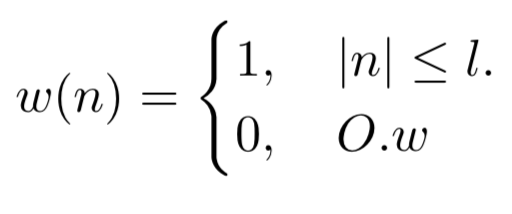

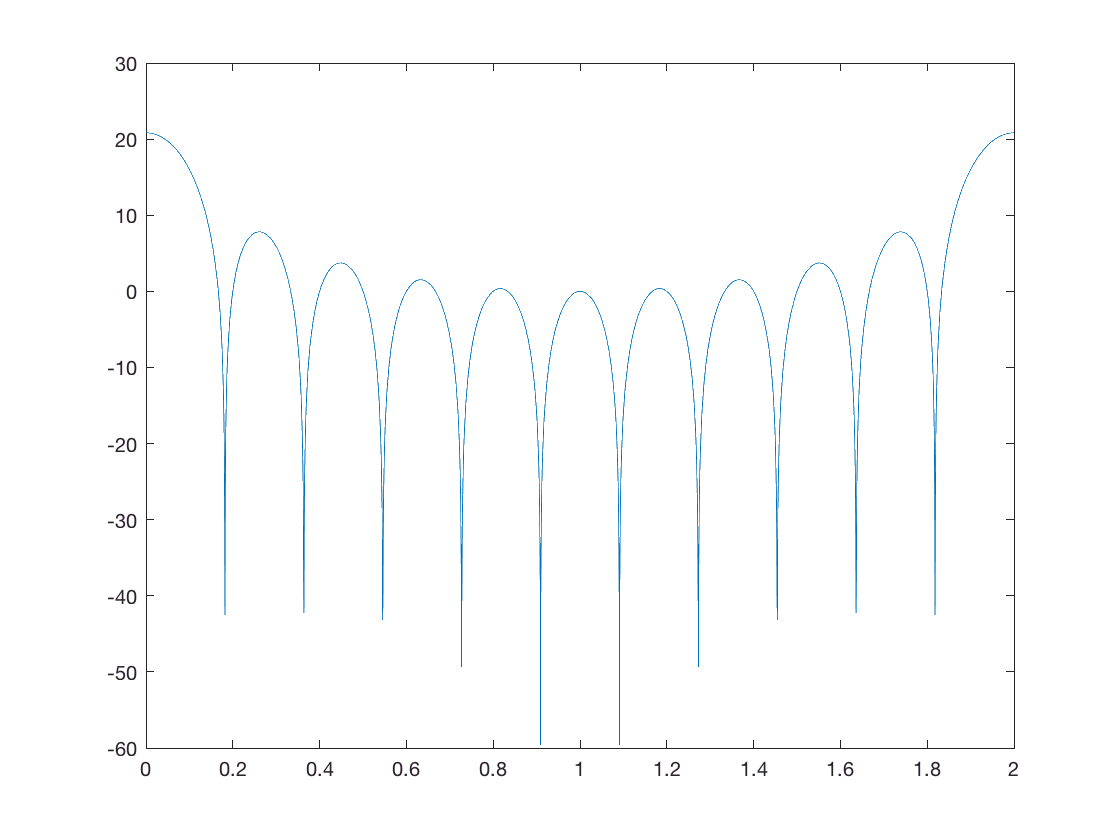

%% l=5
b=[1 1 1 1 1 1 1 1 1 1 1];
a=[0 0 0 0 0 1 0 0 0 0 0];
k=3001;
%%%%
%freqz(b,a)
[h,w] = freqz(b,a,'whole',k);
plot(w/pi,20*log10(abs(h)));

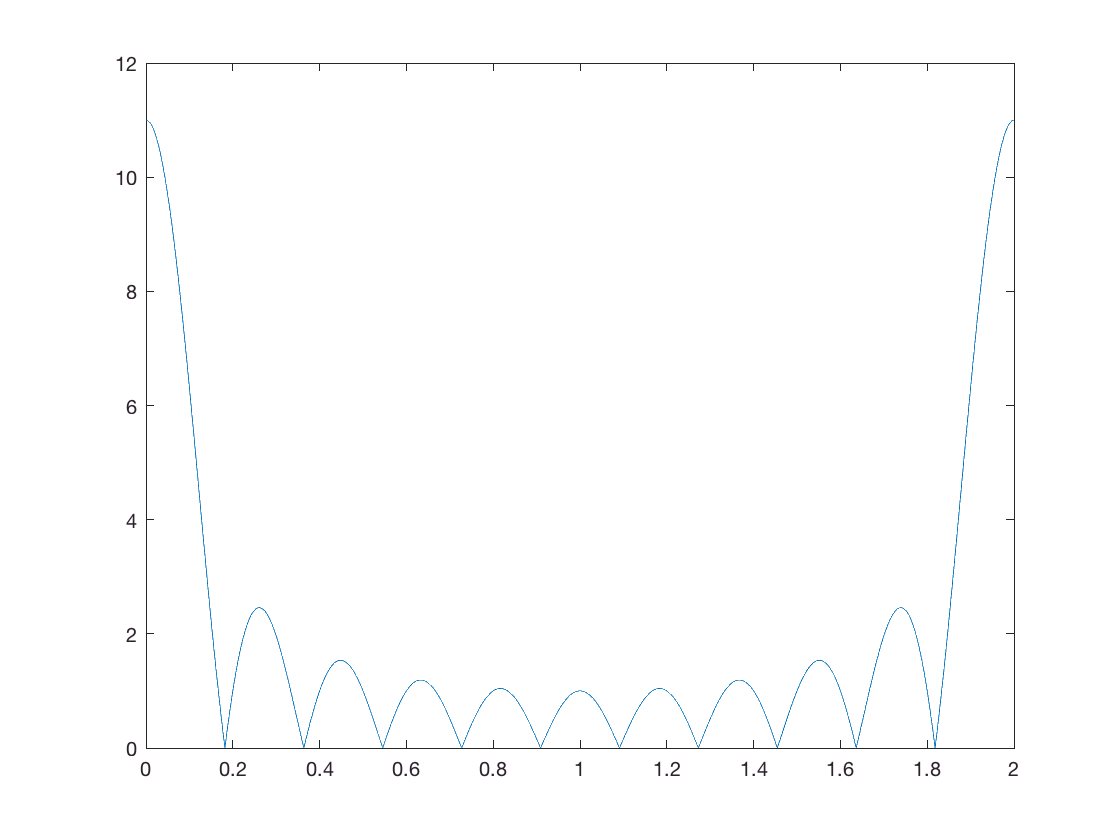


%%
magX = abs(h);
plot(w/pi,magX)

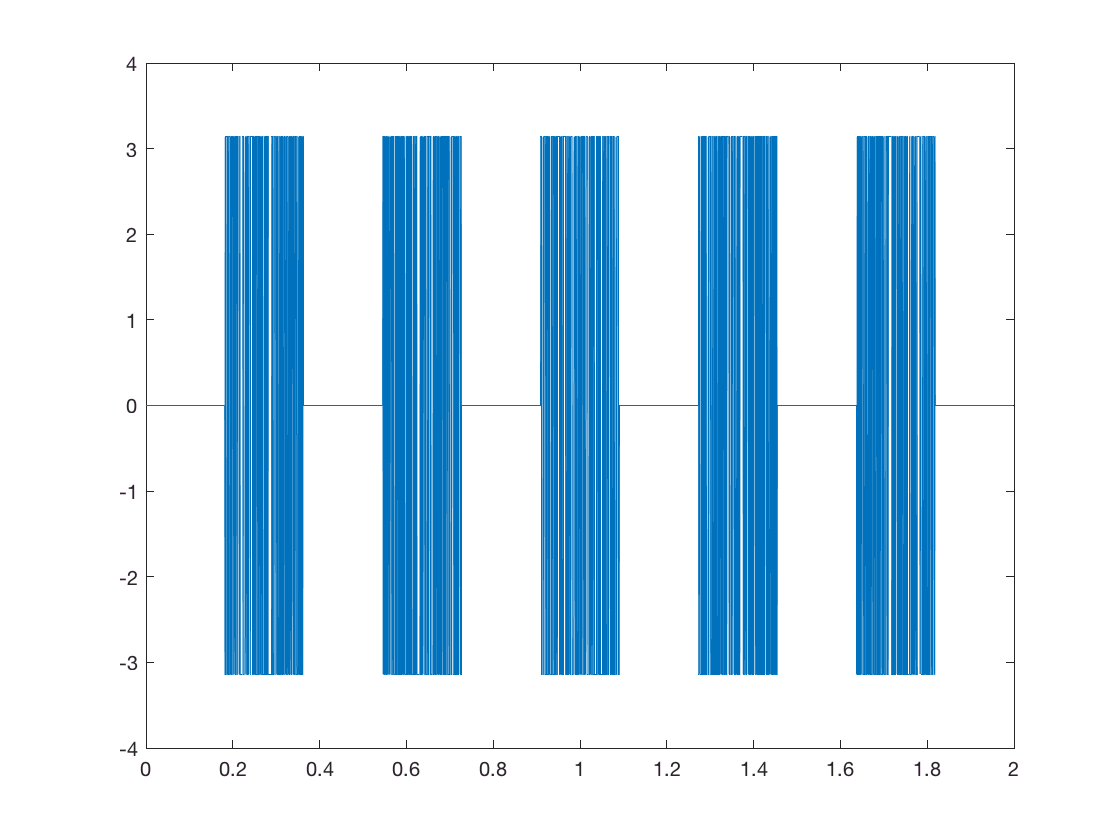

angX=angle(h);

plot(w/pi,angX)

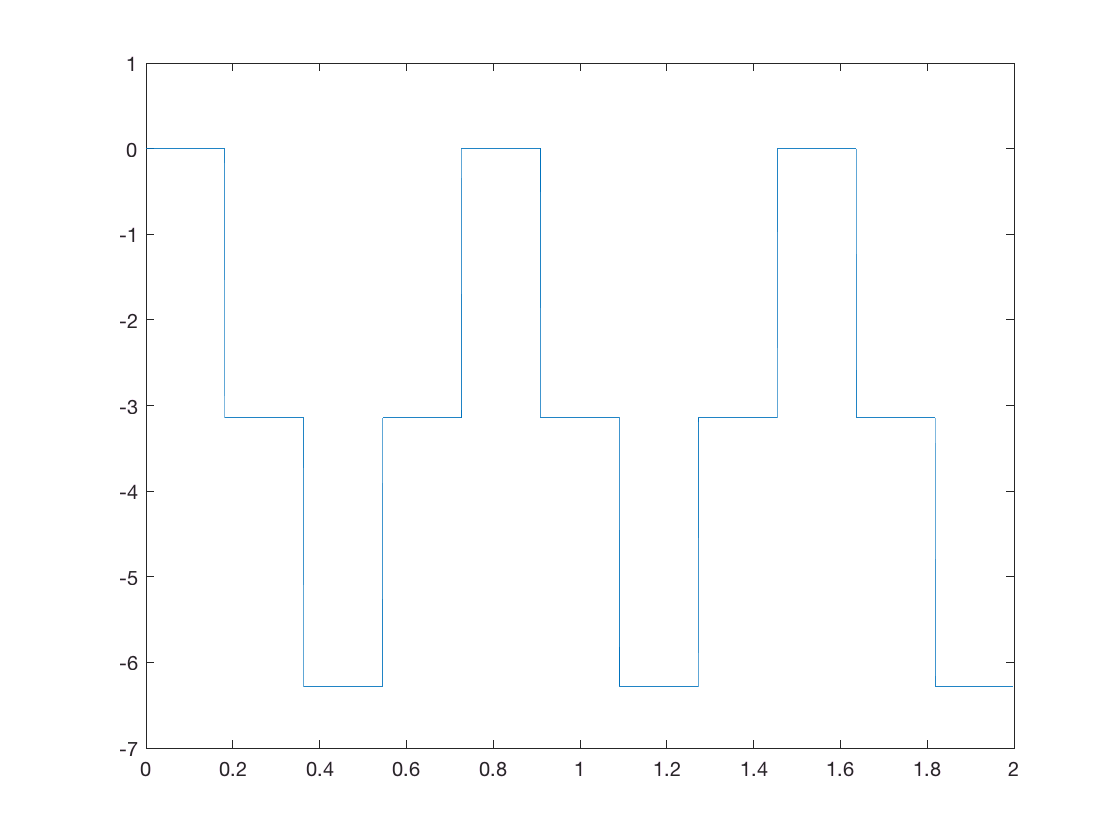

p=unwrap(angX);
plot(w/pi,p)

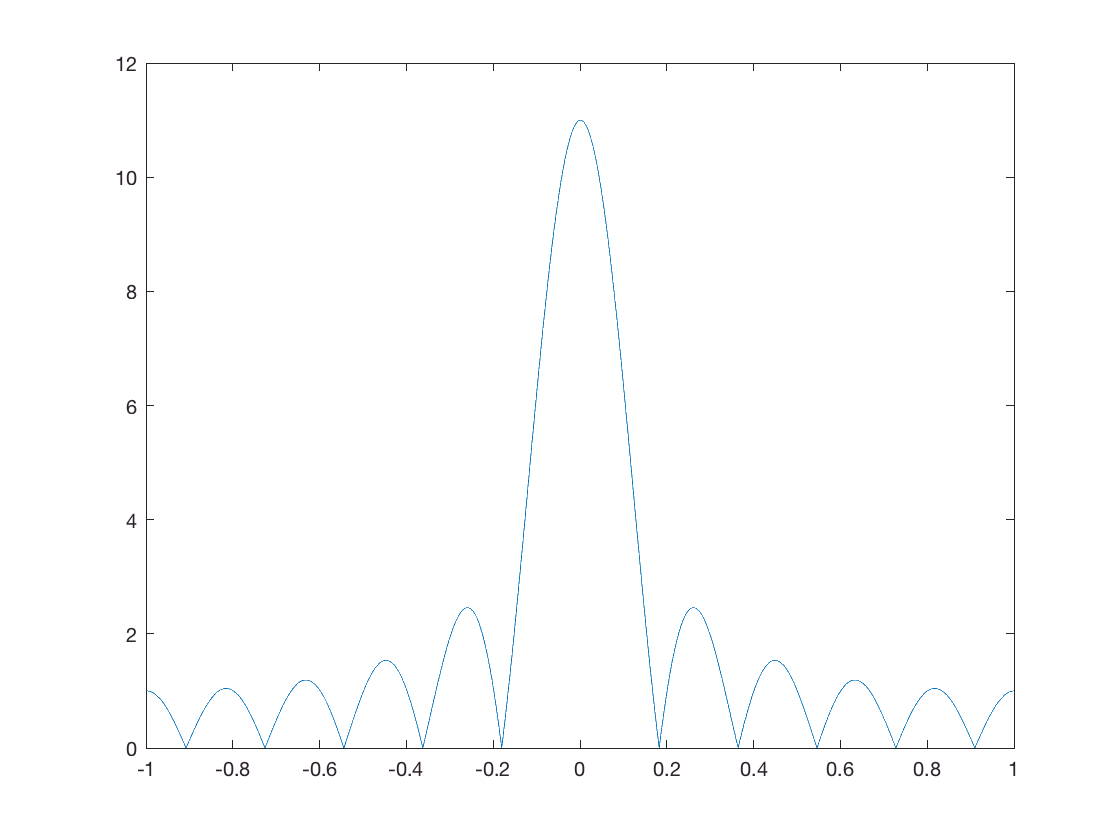

%%%
k1=floor(k/2);
w1=w(1:k1);
w2=[-fliplr(w1(1:end)'),w(1:k1+1)'];
h1=h(k1+1:end);
h2=[h1',h(1:k1)'];
plot(w2/pi,abs(h2))

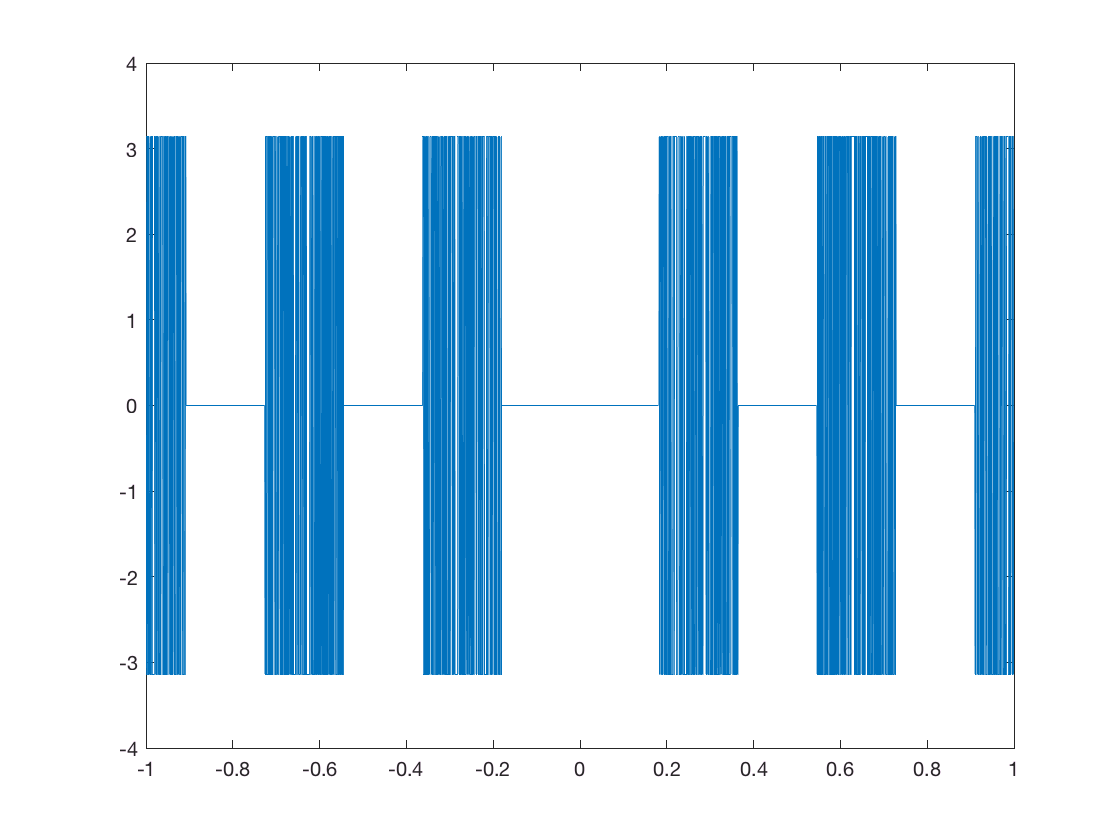

angx2=angle(h2);
plot(w2/pi,angle(h2))

Unwraped phase response using unwrap matlab function

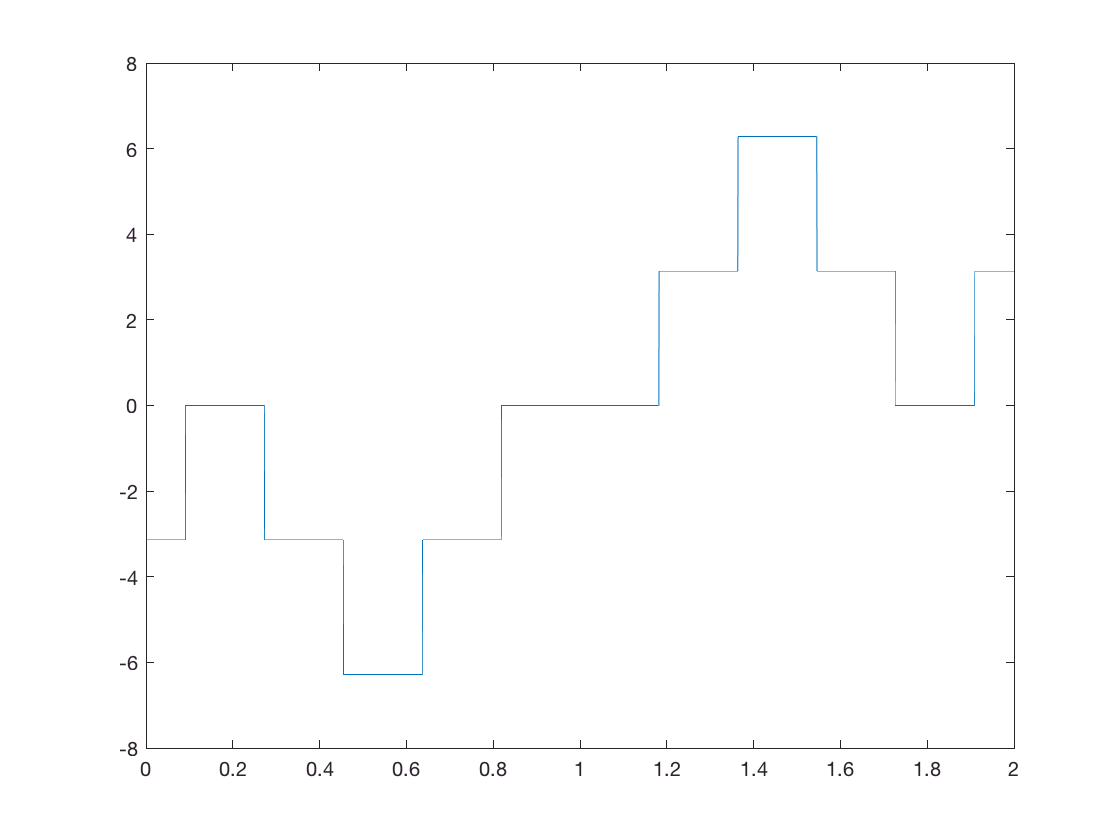

p2=unwrap(angx2);
plot(w/pi,p2)

Unwraped phase response using phasez

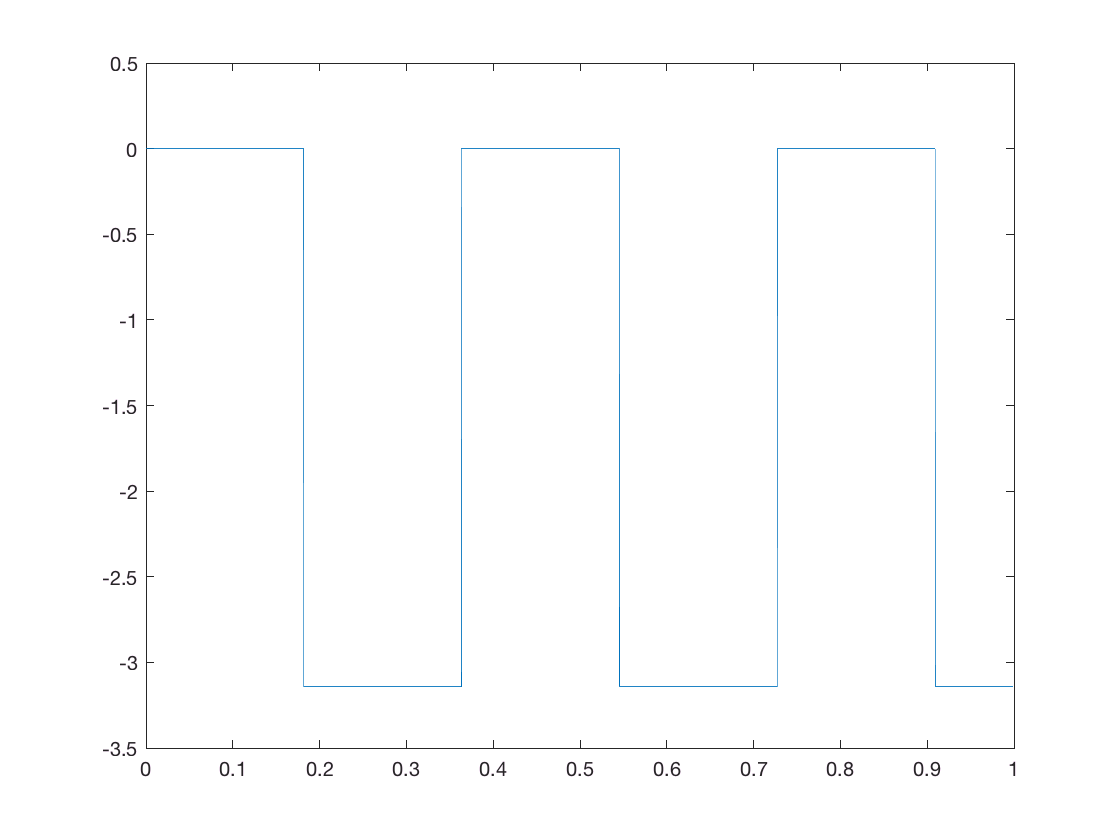

[phi,w] = phasez(b,a,k);
plot(w/pi,phi)

Specify the parameters of a signal with a sampling frequency of 1 kHz and a signal duration of 1 second.

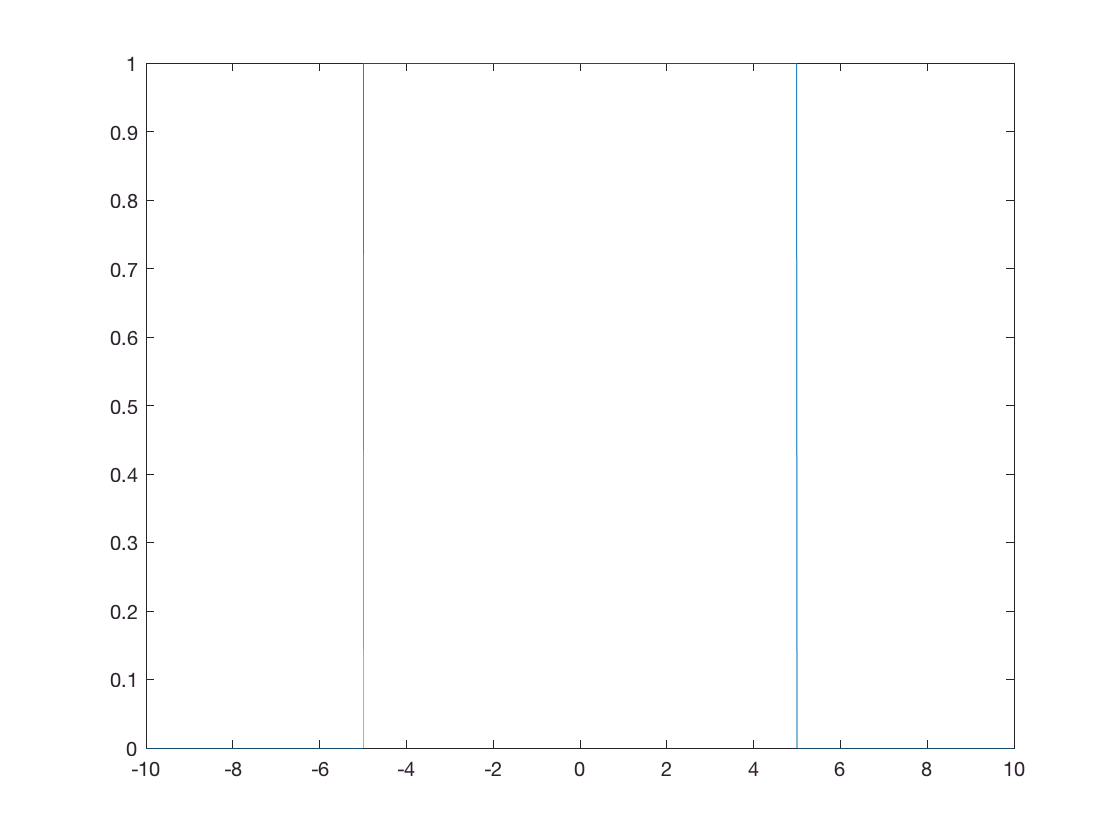

Fs = 100;           % Sampling frequency
t = -10:1/Fs:10;    % Time vector
L = length(t);      % Signal length

X=[(t<5 & t>-5)];
plot(t,X)

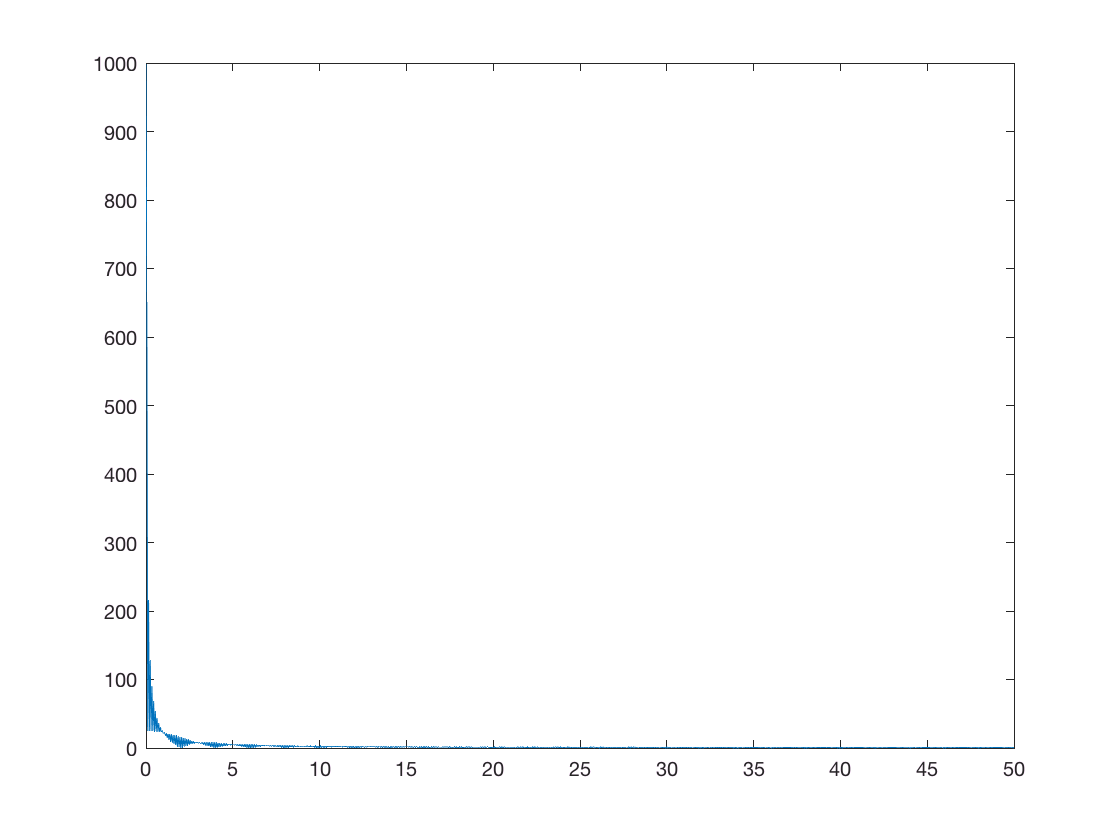

n=2^nextpow2(L);
Y=fft(X,n);
f = Fs*(0:(n/2))/n;
P = abs(Y);

plot(f,P(1:n/2+1))

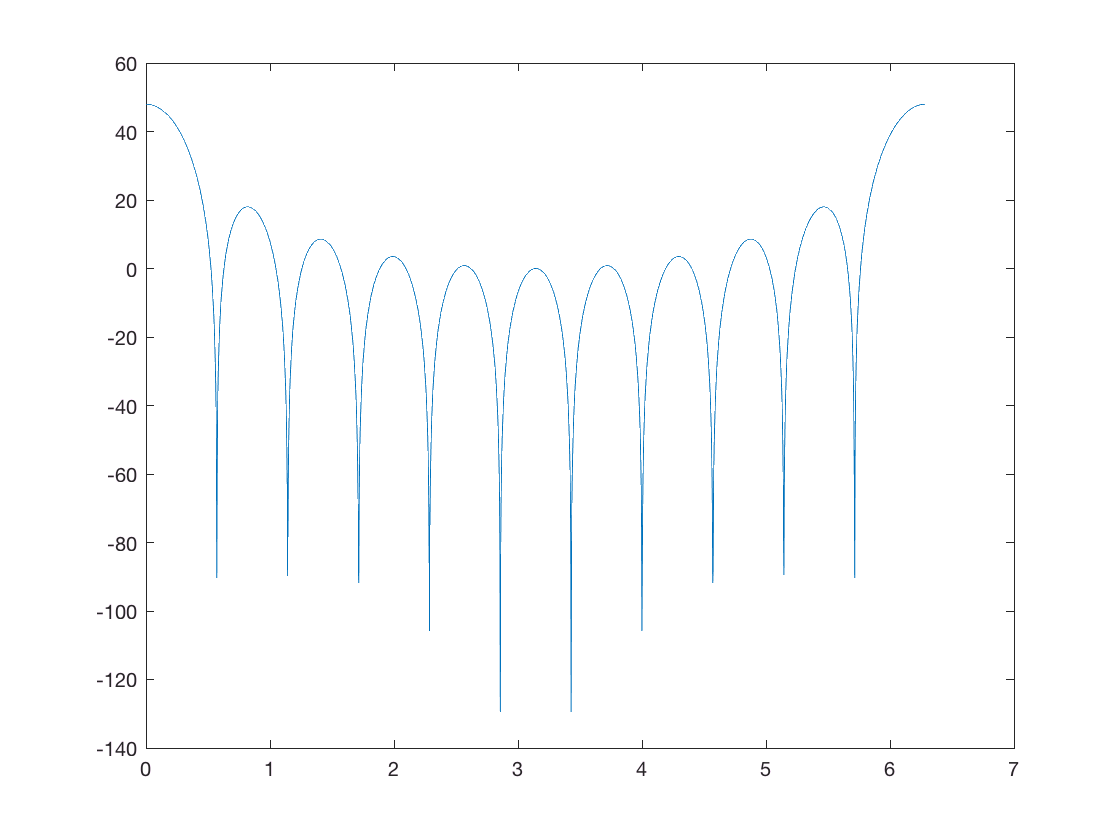

m=-100:100;
m1=[(m>=-5 & m<=5)];
M=fft(m1,2048);
plot(linspace(0,2*pi,length(M)),20*log(abs(M))) %%%so many of you have made this mistake

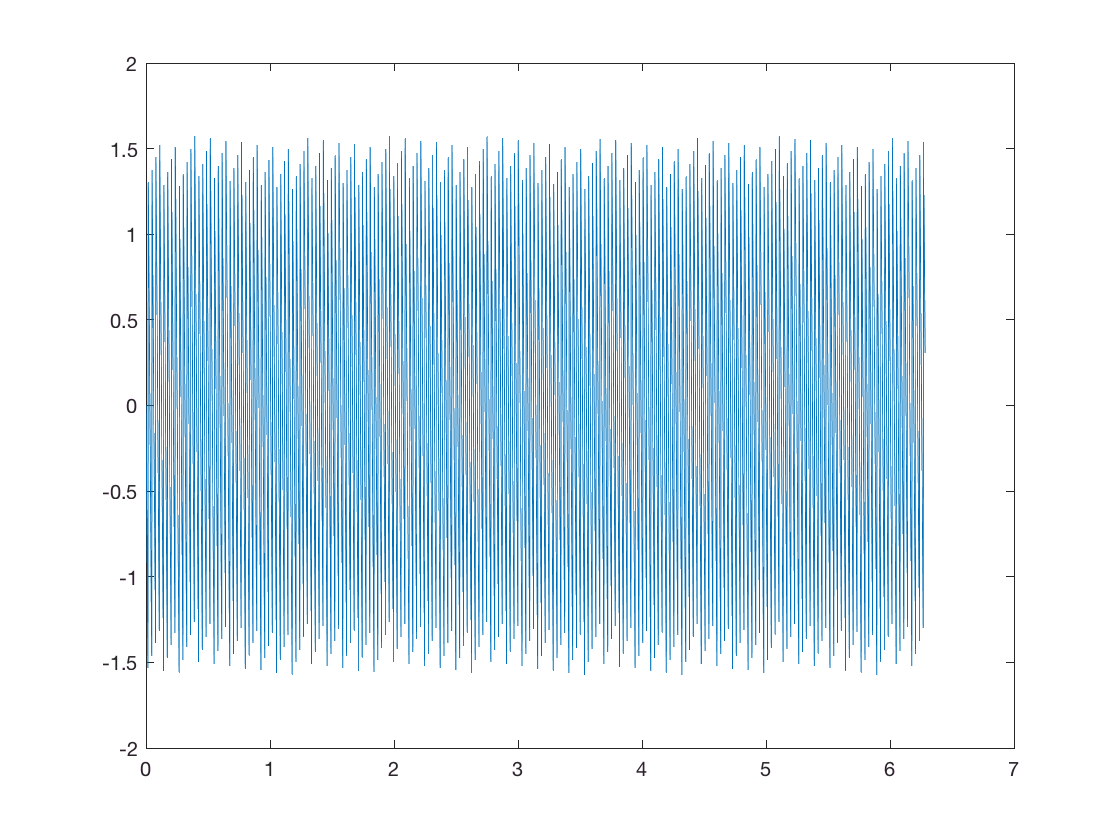

phi=imag(M)./real(M);
plot(linspace(0,2*pi,length(M)),atan(phi))

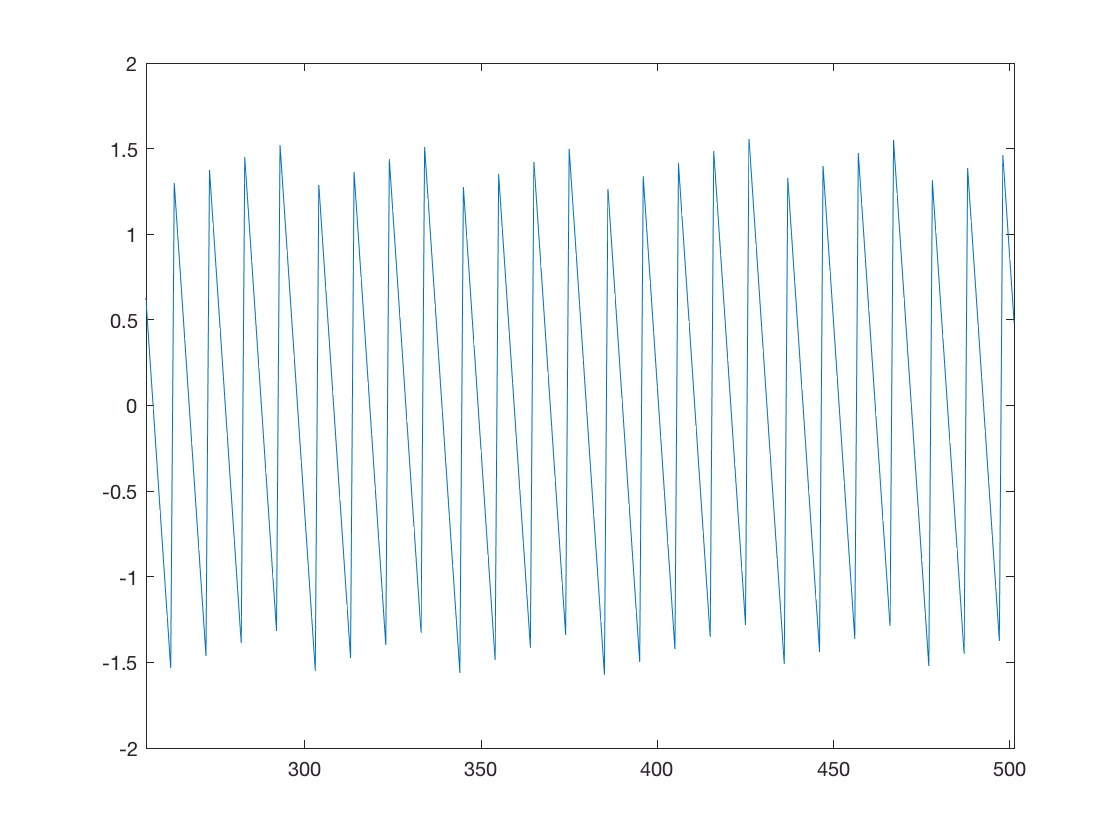

quad2=atan(phi);
pq2=unwrap(quad2);
plot(pq2)

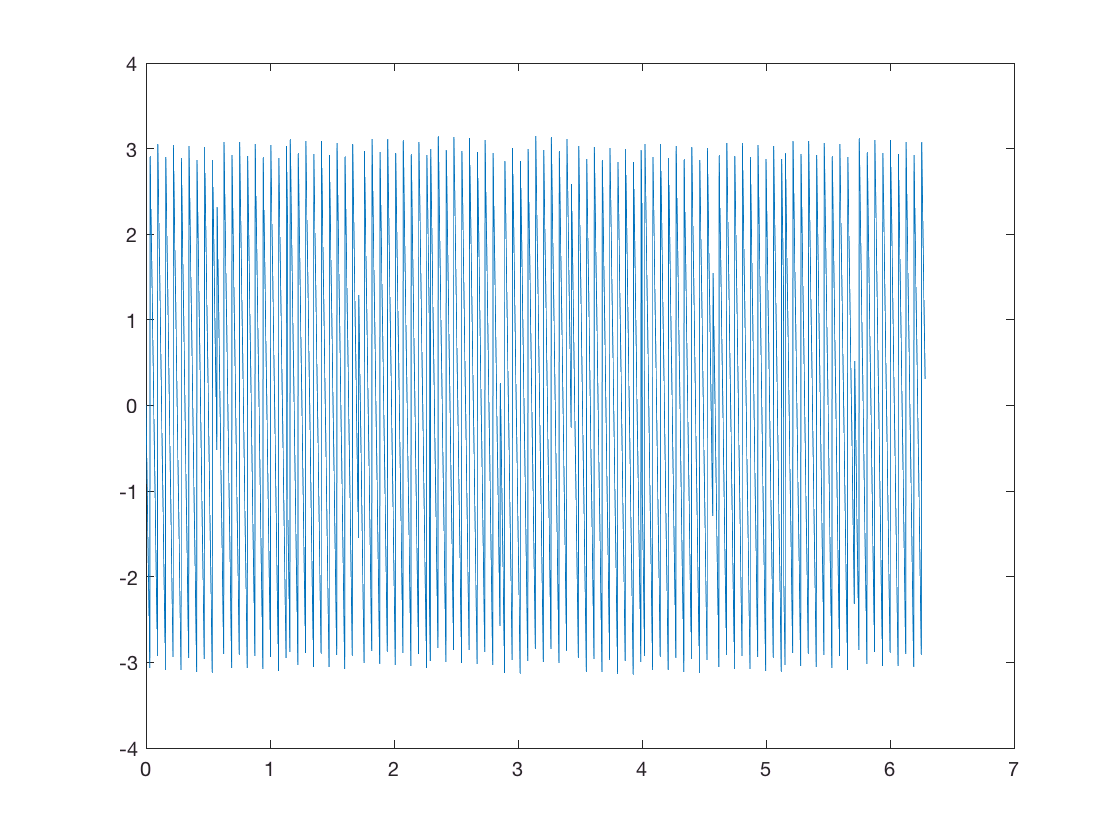

plot(linspace(0,2*pi,length(M)),atan2(imag(M),real(M)))

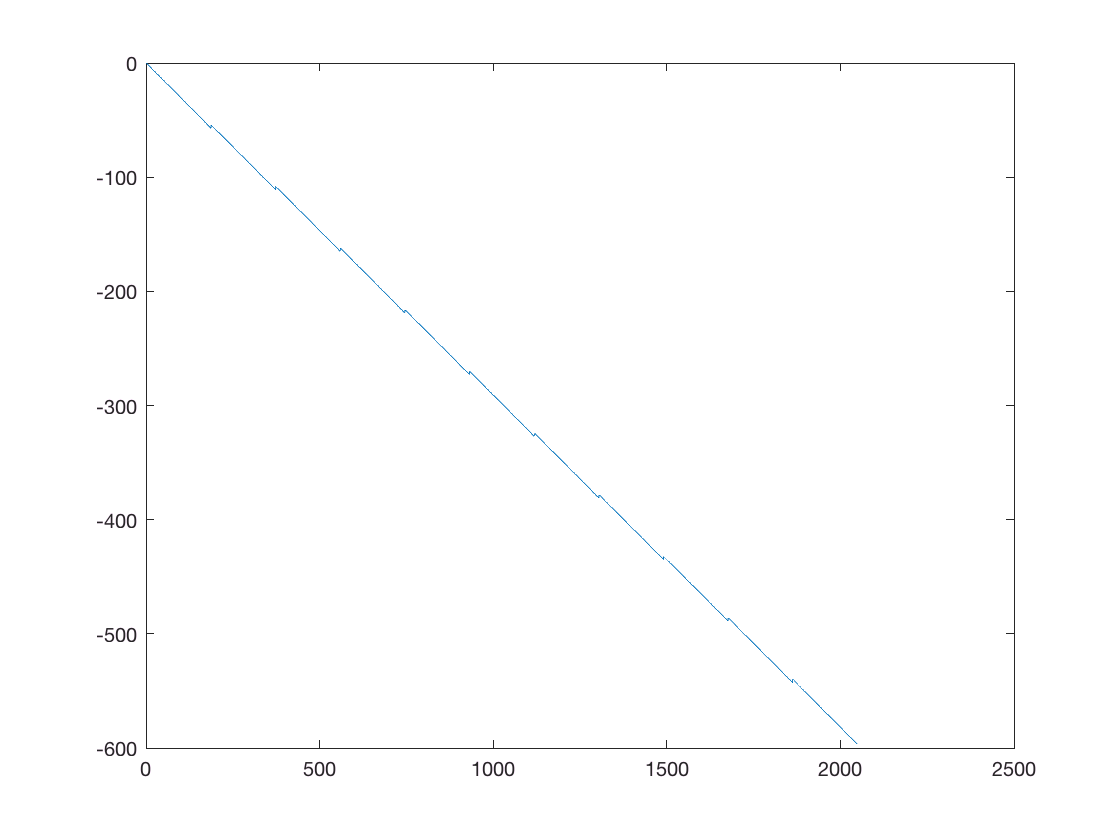

quad4=atan2(imag(M),real(M));
pq4=unwrap(quad4);
plot(pq4)